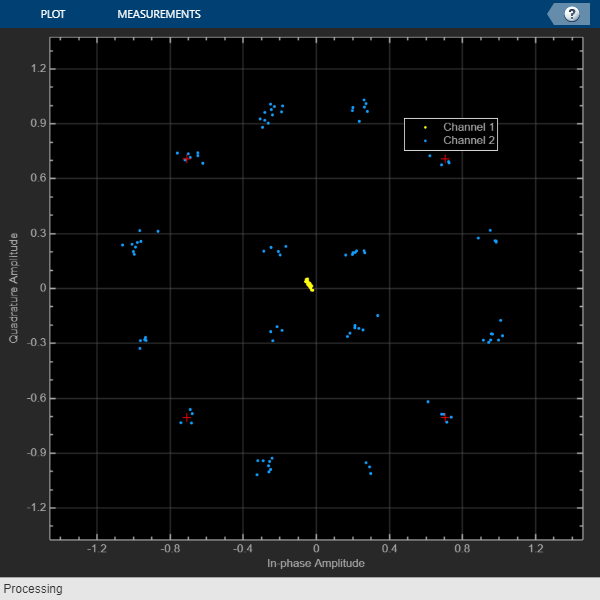

clear all
clc
M = 16;

i = 1;
k = 4; 
for EbNo = [-2, 0, 3, 10, 15, 23, 50]
    
    ber = zeros(1,7); 

    path = 'C:\Users\Martha Ca$h\Desktop\School\Grad School\Research\Python Code\MAT Files\'; 
    f = sprintf('predictionsSNR%02d', EbNo); %recovered data
    f_og = sprintf('Data_SNR%02d', EbNo); %original filename 

    load(strcat(path, f), 'pred'); %predicted, tx
    load(strcat(path,f_og), 'rx_pred', 'tx_pred'); %original tx

    pred = complex(pred(:,1), pred(:, 2)); 

    constDiagram([tx_pred, rx_pred, pred]);

    demodData_NN = dvbsapskdemod(pred, M, 's2x', '2/3'); 
    demodData_ideal = dvbsapskdemod(tx_pred, M, 's2x', '2/3'); 

    %calculate BER
    data_bit = int2bit(demodData_ideal, k); %convert to bit
    output_bit = int2bit(demodData_NN, k);%convert to bit
    
    d = finddelay(data_bit,output_bit); 
    errorRate = comm.ErrorRate('ReceiveDelay', d);
    err = errorRate(demodData_ideal, demodData_NN); %get bit error
    bit_err = err(1)*100
    
    ber(i) = bit_err;
    i = i+1;

end 